# Spreading the butter for Diffusion

## © 2017 Griffin Chure. This work is licensed under a [Creative Commons Attribution License CC-BY 4.0](https://creativecommons.org/licenses/by/4.0/). All code contained herein is licensed under an [MIT license](https://opensource.org/licenses/MIT).

In this tutorial, we will cover the basics of solving the diffusion equation determinstically and examine an interesting use of diffusion to measure the mobility of biological molecules.

## Another view of diffusion

As we have seen over and over again, diffusion is a central concept in our understanding of how life operates. The principles of diffusion can shed light on how molecules travel within cells and organisms, to herd migration, to changing of allele frequencies over time. In this course, we've examined the case of a one-dimensional random walk and its connection to diffusion in an earlier tutorial where we performed repeated trials of coin flips to get a picture of the probability distribution of position as a function of time.

Rather than relying on our computer to flip a seemingly infinite number of coins, we can compute the distribution deterministically using something called a chemical master equation. In this approach we consider all of the possible ways particles can move in a discretized system at very small time steps and keeping track of either the number of particles around or the probability of being at that position at a specific time.

Let's be more explicit and draw some cartoons. Let's imagine that we live in a one-dimensional world. Along this dimension, we have a string of boxes of a width  $a=1$ which can either be empty or contain a particle. At any point in time, a given particle can move to either the left or right at some rate  $k$, which we'll call the jump frequency, or it can stay put. A cartoon of these trajectories and their weights is shown below.

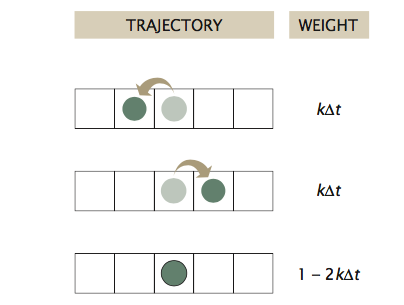

These weights can be used to formulate our master equation. We simply have to say, given the probability  $p$ of a particle being at position  $x$ at time $t$, what's the probability at time  $t+Δt$ knowing the jump frequency $k$. We'll have to keep track of the movement of particles from our box of interest as well as the movement of particles from the boxes on the left and right into our box. Mathematically, this is written as


$$p(x, t + \Delta t) = \overbrace{p(x, t)}^\text{starting probability} + \underbrace{k\Delta tp(x- a,t)}_\text{jump from left} + \underbrace{k\Delta tp(x + a, t)}_\text{jump from right} - \overbrace{2k\Delta t p(x, t)}^\text{jump to right or left}. \;\; (1)$$


Because we now have the superpower of scientific programming, we can write a few lines of code to integrate this equation over a period of time and keep track of all of the probabilities.

## A refresher on numerical integration

At the beginning of the course, you learned how to write a program to perform a Forward-Euler integration of a ordinary differential equation. We'll be performing essentially the same procedure to evaluate Eq. 1, but we have a few peculiarities of this approach that we'll have to keep in the back of our mind.

Firstly, unlike our exploration of radioactive decay, we will be integrating over time *as well as over position*. This means that we will have set up an array where we can store the computed probability of finding a particle in each box over a range of time points.

Secondly, we have to be wary of the boundary conditions. Since we are solving this numerically on our computers, we can't have a truly infinite number of boxes. This means that we will have to be a little careful of how we compute the probabilities at the edges. For example, if we are computing the probability in our first box, we know that the particle can only jump into the box to the right, or stay put. You can think of this box being against a wall where things can't pass through. Likewise, we have the same condition in the final box where particles can only jump to the left or stay put.

For example, let's say that we are thinking of a system with only ten boxes. Our boundary condition for the first box (box 1), would be


$$p(x=1, t + \Delta t) = p(x=1, t) + k\Delta t p(x=2, t) - k\Delta t p(x=1, t). \;\; (2)$$


Similarly, for our final box ($x=10$), our master equation is


$$p(x=10, t + \Delta t) = p(x=10, t) + k\Delta t p(x=9, t) - k\Delta t p(x=10, t). \;\;(3)
$$


Knowing these two requirements, we can write a general function for our master equation for any number of boxes and time points.

`bulding the function...`

Now that we have our function in place, let's test it out. We'll think of a very simple case in which we have a very long string of boxes which are all empty, except for one right in the middle which will have an initial probability  $p(x=\text{middle},t=0)=1.0
$. You can think of this as adding a pulse of dye molecules within the cell cytoplasm or some carbon atoms in iron in the making of steel. We will expect that as time goes on, we'll watch the concentration profile broaden. We'll start by defining our parameters.

% Define the parameters
k = 5; % Jump frequency in inverse seconds.
dt = 1 / 50; % Time step sufficiently smaller than the jumpt frequency
numBoxes = 80; % total number of boxes
timeSteps = 100; % total time of the integration in units of seconds

Here, I've taken the liberty of setting our time step to something much smaller than our jump rate. As was discussed in the Euler method tutorial, we have to choose very short time steps for numerical stability. It won't be very enlightening if we take a large enough time step such that a particle can bounce between three different boxes before we take stock of the probabilities!

The next component we need to define is our storage array for the probabilities and set the intial condition. We'll set it up such that it is 80 boxes wide and we'll watch the diffusion over 100 time steps.

% set up the initial probability array and the initial condition
prob = zeros(numBoxes, timeSteps);

% For the fisrt example the initial condition will be a delta funciton in the middle of our box
initialPosition = round(numBoxes / 2);
prob(initialPosition, 1) = 1;

Now that we have the probability array generated and the initial condition in place, let's run the actual integration!

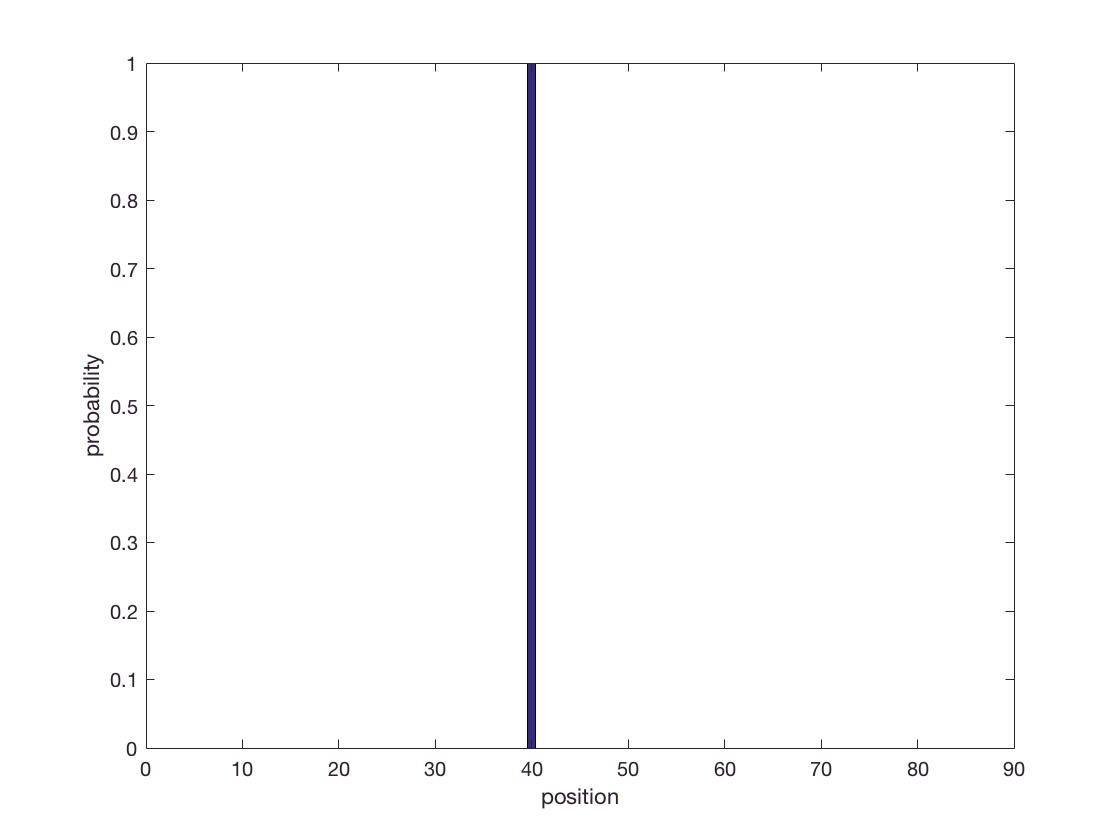

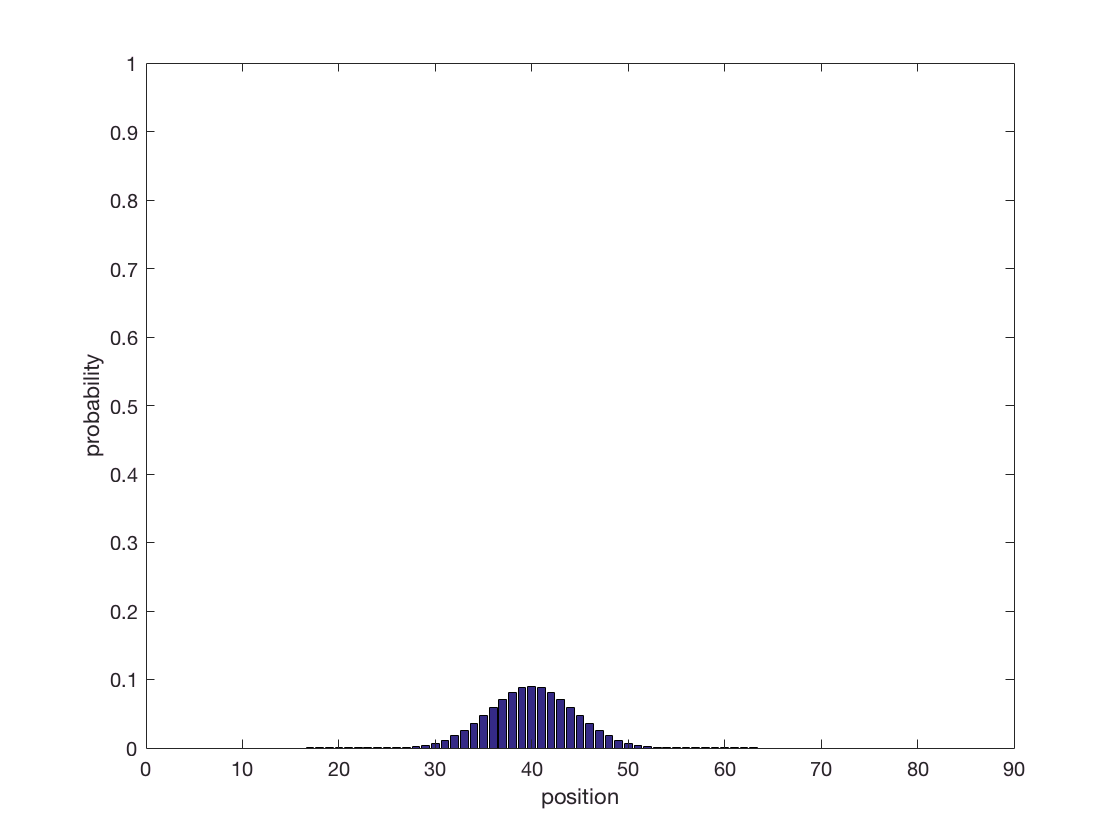

% execute the integration
probInt = masterEquation(prob, k, dt);

We can now display the result of this integration. To have a nice animation we cannot plot it directly here on the *Live script, *but here is the code you can copy and paste (or even better write by yourself) in order to see the result.

`figure()`

`for i=1:timeSteps`

`    bar(1:numBoxes, probInt(:, i));`

`    ylim([0, 1]);`

`    xlabel('position');`

`    ylabel('probability');`

`    pause(0.05);`

`end %for`

The advantage of having this function is that we can easily re-use it for a different initial condition.

We can see that as we defined, the entire probability at $t=0$ is located within the middle of the box. However, just one time point later, we can see that there is now non-zero probability at being to the left or right of where we started. By ten time steps, we can see that the distribution is broadening significantly. By 100 steps, the profile looks very Gaussian.

Hopefully, this wasn't too much of a surprise! Let's now turn the tables and think of a slightly more interesting case. When we wrote our function, we paid special attention to the boundary conditions. However, in the above case, we never actually reached the boundaries! Let's reduce the number of boxes while keeping all of the other parameters the same so we can see what happens when particles start bumping against the walls.

numBoxes = 9; % total number of boxes
prob = zeros(numBoxes, timeSteps); % set matrix for dimension
prob(5, 1) = 1; % set initial condition to be delta function in the middle

% run simulation
probInt = masterEquation(prob, k, dt);

And we plot it again using the same code as above.

By the end of our integration, we can certainly see that we've "filled up the box" such that we will find a particle in any box with equal probability. For fun, try changing this starting condition such that there is a peak at one end of the box rather than in the middle!

As a final illustration of this description of diffusion, let's look a common experimental method in cell biology − FRAP.

## The annoying process of photobleaching

The advent of fluorescent labelling has transformed our ability to ask biological questions. As we have seen numerous times in class, we can get a sense for how molecules move, how genes are regulated, and where things are localized by hooking the various components up to fluorescent proteins.

However, fluorescent proteins are not fluorescent forever. All fluorescent molecules can undergo a process known as photobleaching where sustained excitation can lead to the permanent chemical inactivation of the fluorophore. While this is a process that is true for all fluorescent molecules, fluorescent proteins are particularly susceptible to this phenomenon.

While this can be an annoying phenomenon to correct for in your experiment, others have found ways to turn lemons into lemonade and use photobleaching as an experimental tool. A fantastic example of this use is an experimental method named [**F**luorescence **R**ecovery **A**fter **P**hotobleaching](https://en.wikipedia.org/wiki/Fluorescence_recovery_after_photobleaching), or FRAP for short. This method allows us to make measurements of how mobile a particular molecular species is in a cell. This is commonly used for making mobility measurements of proteins within the cell membrane.

The general scheme of a FRAP experiment is as follows:

1). Attach a fluorescent dye or protein to your molecule of interest. If this is something like a membrane protein, you would imagine that the fluorescence of the membrane would now be relatively uniform in space if there isn't any complicated localization.

2). Illuminate a small section of your field of view with a high-power laser to photobleach all of the fluorescent molecules. All of the molecules outside of this small section will still be fluorescent, but there will now be a "hole" where there is no fluorescence.

3). Take a series of images over time and measure the rate at which the hole becomes fluorescent again. This return of fluorescence is not reactivation of the bleached molecules, however. This is due to the nearby fluorescent molecules diffusing into the hole.

An example of this can be seen below. In 2010, [Nate Goehring](https://goehringlab.crick.ac.uk/) from the Francis Crick Institute published [a beautiful paper](https://goehringlab.crick.ac.uk/biophysicaljournal2010goehr.pdf) performing a detailed quantitative analysis of FRAP measurements and examined the diffusion rate of fluorescent molecules within a C. elegans cell membrane as well as the diffusion rate between the cell cytoplasm and the membrane. The authors examined multiple geometries of bleaching patterns and wrote some open source software that is meant to aid others in performing this type of rigorous experiment.

Figure 1 of this paper shows a representative FRAP experiment and the quantified fluorescence at the beginning and end of the movie.

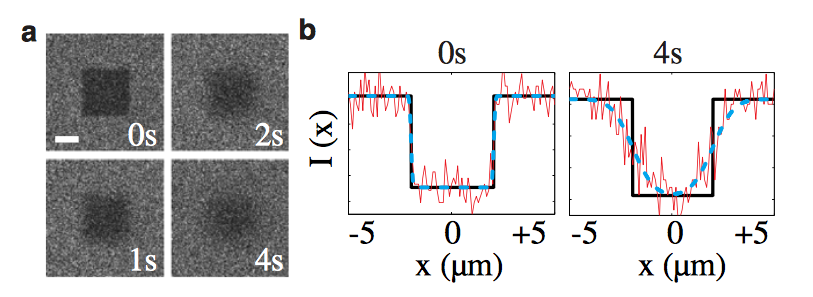

The astute observer will realize that we can simulate this experiment by integrating Eq. 1 with a special initial condition. To set the intial condition, we'll set the probability equal across all of the boxes save for a few right in the middle which will serve as our photobleached "hole". Let's give it a shot.

%  Set the box dimensions
numBoxes = 20;
timeSteps = 300;
prob = zeros(numBoxes, timeSteps);

%  Set the initial condition. We'll leave 6 boxes in the middle empty 
bleachSize = 6;
prob(:,1) = 1 / (numBoxes - bleachSize);

%  Set the region where we bleached equal to zero. 
prob(7:13, 1) = 0;

%  Integrate!
probInt = masterEquation(prob, k, dt);

Now we can see that the hole we bleached in our simulated membrane is filling up as molecules diffuse in from the left and right. You should also notice that the height of the bars on the extreme left and right side are decreasing. If we were to think of the height of these bars as a measure of fluorescence, this translates to a decrease in fluorescence of the nearby boxes as the hole is filled.